# Create Simple Image Classification Network

The example demonstrates how to: 

- Load image data.

- Define the network architecture.

- Specify training options.

- Train the network.

- Predict the labels of new data and calculate the classification accuracy.

## Load Data

Load the digit sample data as an image datastore. The `imageDatastore` function automatically labels the images based on folder names.

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');

imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

numTrainFiles = 750;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomized');

inputSize = [28 28 1];
numClasses = 10;

layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

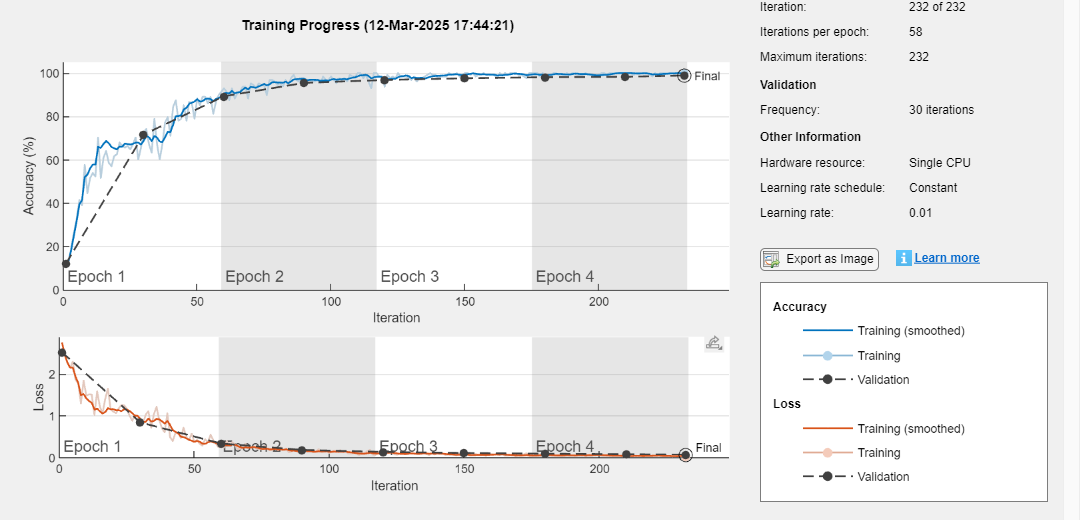

options = trainingOptions('sgdm', ...
    'MaxEpochs',4, ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

net = trainNetwork(imdsTrain,layers,options);

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.9892